# Identify a SINDy model on forced Duffing oscillator data

- Forced Duffing oscillator dynamics: 

                     
$$\ddot{x} +\delta \dot{x} +\alpha x+\beta x=\gamma \;\cos \left(\omega \;t\right)$$


- Convert to first order ODE

                    
$${\dot{x} }_1 =-\delta x_1 -\alpha x_2 -\beta x_2 +\gamma \;\cos \left(\omega \;t\right)$$


                    
$${\dot{x} }_2 =x_1$$


- Generate (noisy) data: integrate Duffing oscillator system ODE and add Gaussian white noise

- Compute derivatives: using finite difference

- Build library

- Compute sparse regression

- Evaluate performance of SINDy model for forecasting

addpath(genpath(pwd))

## Generate Data

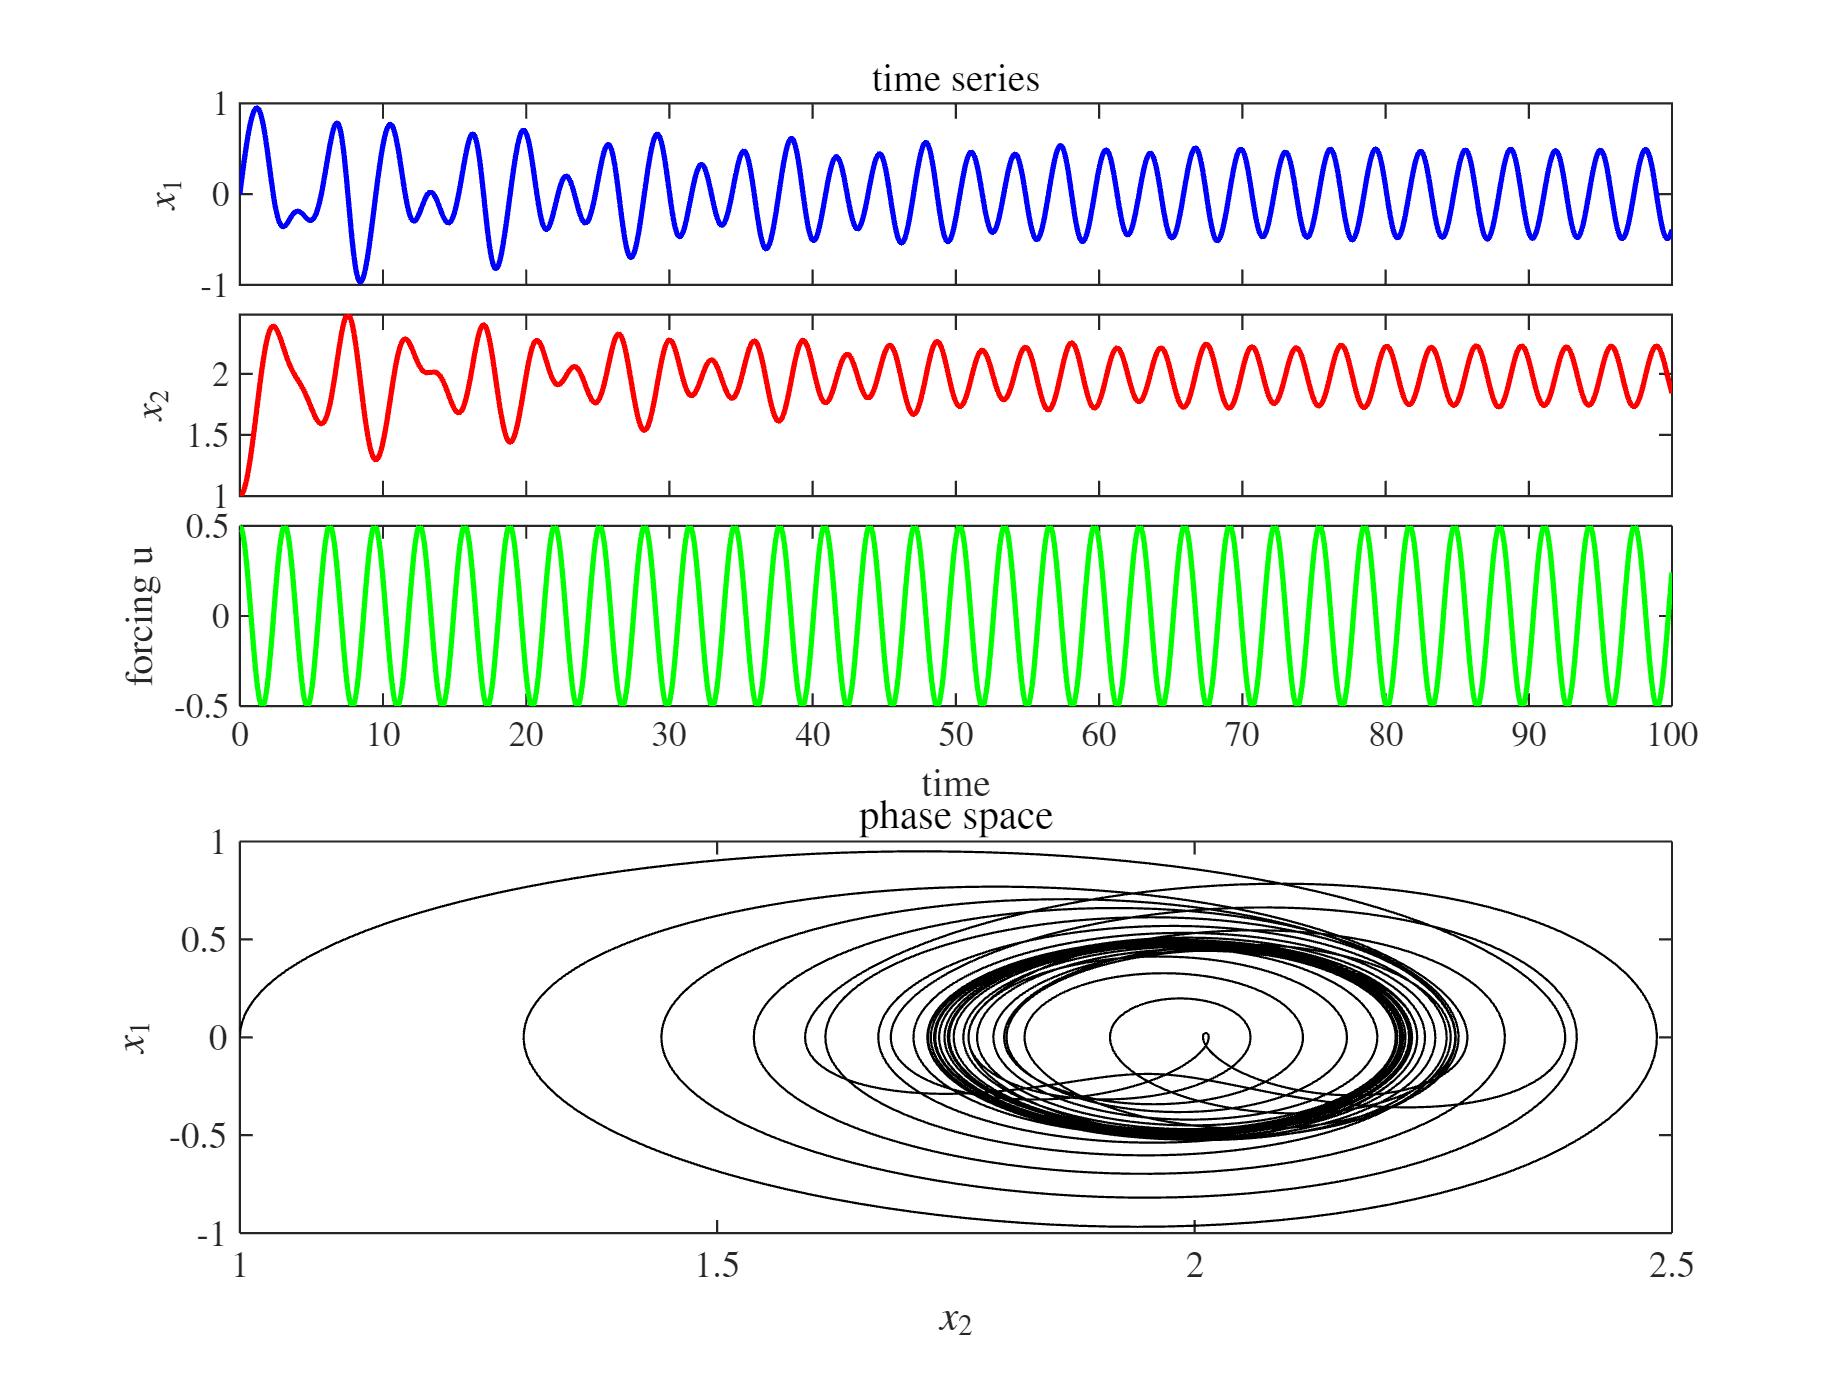

% Duffing oscillator parameters
delta = 0.1;
alpha = -1;
beta  = 0.25;
omega = 2;
gamma = 0.5; % limit cycle
% gamma = 1.5; % chaotic

param = [delta, alpha, beta, gamma, omega]; 
n = 2; % number of states (unforced)
x0 = [0; 1];  % Initial condition
dt = 2*pi/omega/100; % time step
tspan = 0:dt:100; 
options = odeset('RelTol',1e-12,'AbsTol',1e-12*ones(1,n));
[t,x]=ode45(@(t,x) duffing(t,x,param),tspan,x0,options);

% Add Gaussian white noise
rng(1)
sig = 0;%0.001; 
x = x + sig*std(x(:))*randn(size(x)); 

% forcing
u = gamma*cos(omega*tspan);

plotForcedDuffing(t,x,u) % plot data

% animateDuffing(t,x) % animate duffing oscillator data

## Compute Derivative: finite difference

% fourth order central difference
dx = (1/(12*dt))*(-x(5:end,:)+8*x(4:end-1,:)-8*x(2:end-3,:)+x(1:end-4,:)); 

x = x(3:end-2,:); % cut tails
t = t(3:end-2,:);

% add forcing to state matrix
x = [x, u(:,3:end-2)']; % forcing u is added to the data matrix 
dx = [dx, 0*u(:,3:end-2)']; % forcing also added to "derivatives", but set to zero

n = n + 1; % number of states is increased by 1 -> forcing "state"

## Pool Data (i.e., build library of nonlinear time series)

polyorder = 3; % polynomials up to order 3
Theta = poolData(x,n,polyorder);
m = size(Theta,2); % size of library

## Compute sparse regression: sequential thresholded least squares

lambda = 0.05; % lambda is our sparsification knob.
Xi = sparsifyDynamics(Theta,dx,lambda,n); % identify model coefficients
disp(poolDataLIST({'x1','x2','u'},Xi,n,polyorder)) % display SINDy model

    {0×0 char}    {'x1dot'  }    {'x2dot' }    {'udot'}
    {'1'     }    {[      0]}    {[     0]}    {[   0]}
    {'x1'    }    {[-0.1000]}    {[1.0000]}    {[   0]}
    {'x2'    }    {[ 1.0000]}    {[     0]}    {[   0]}
    {'u'     }    {[ 1.0000]}    {[     0]}    {[   0]}
    {'x1x1'  }    {[      0]}    {[     0]}    {[   0]}
    {'x1x2'  }    {[      0]}    {[     0]}    {[   0]}
    {'x1u'   }    {[      0]}    {[     0]}    {[   0]}
    {'x2x2'  }    {[      0]}    {[     0]}    {[   0]}
    {'x2u'   }    {[      0]}    {[     0]}    {[   0]}
    {'uu'    }    {[      0]}    {[     0]}    {[   0]}
    {'x1x1x1'}    {[      0]}    {[     0]}    {[   0]}
    {'x1x1x2'}    {[      0]}    {[     0]}    {[   0]}
    {'x1x1u' }    {[      0]}    {[     0]}    {[   0]}
    {'x1x2x2'}    {[      0]}    {[     0]}    {[   0]}
    {'x1x2u' }    {[      0]}    {[     0]}    {[   0]}
    {'x1uu'  }    {[      0]}    {[     0]}    {[   0]}
    {'x2x2x2'}    {[-0.2500]}    {[     0]}    {

## Use SINDy model for prediction

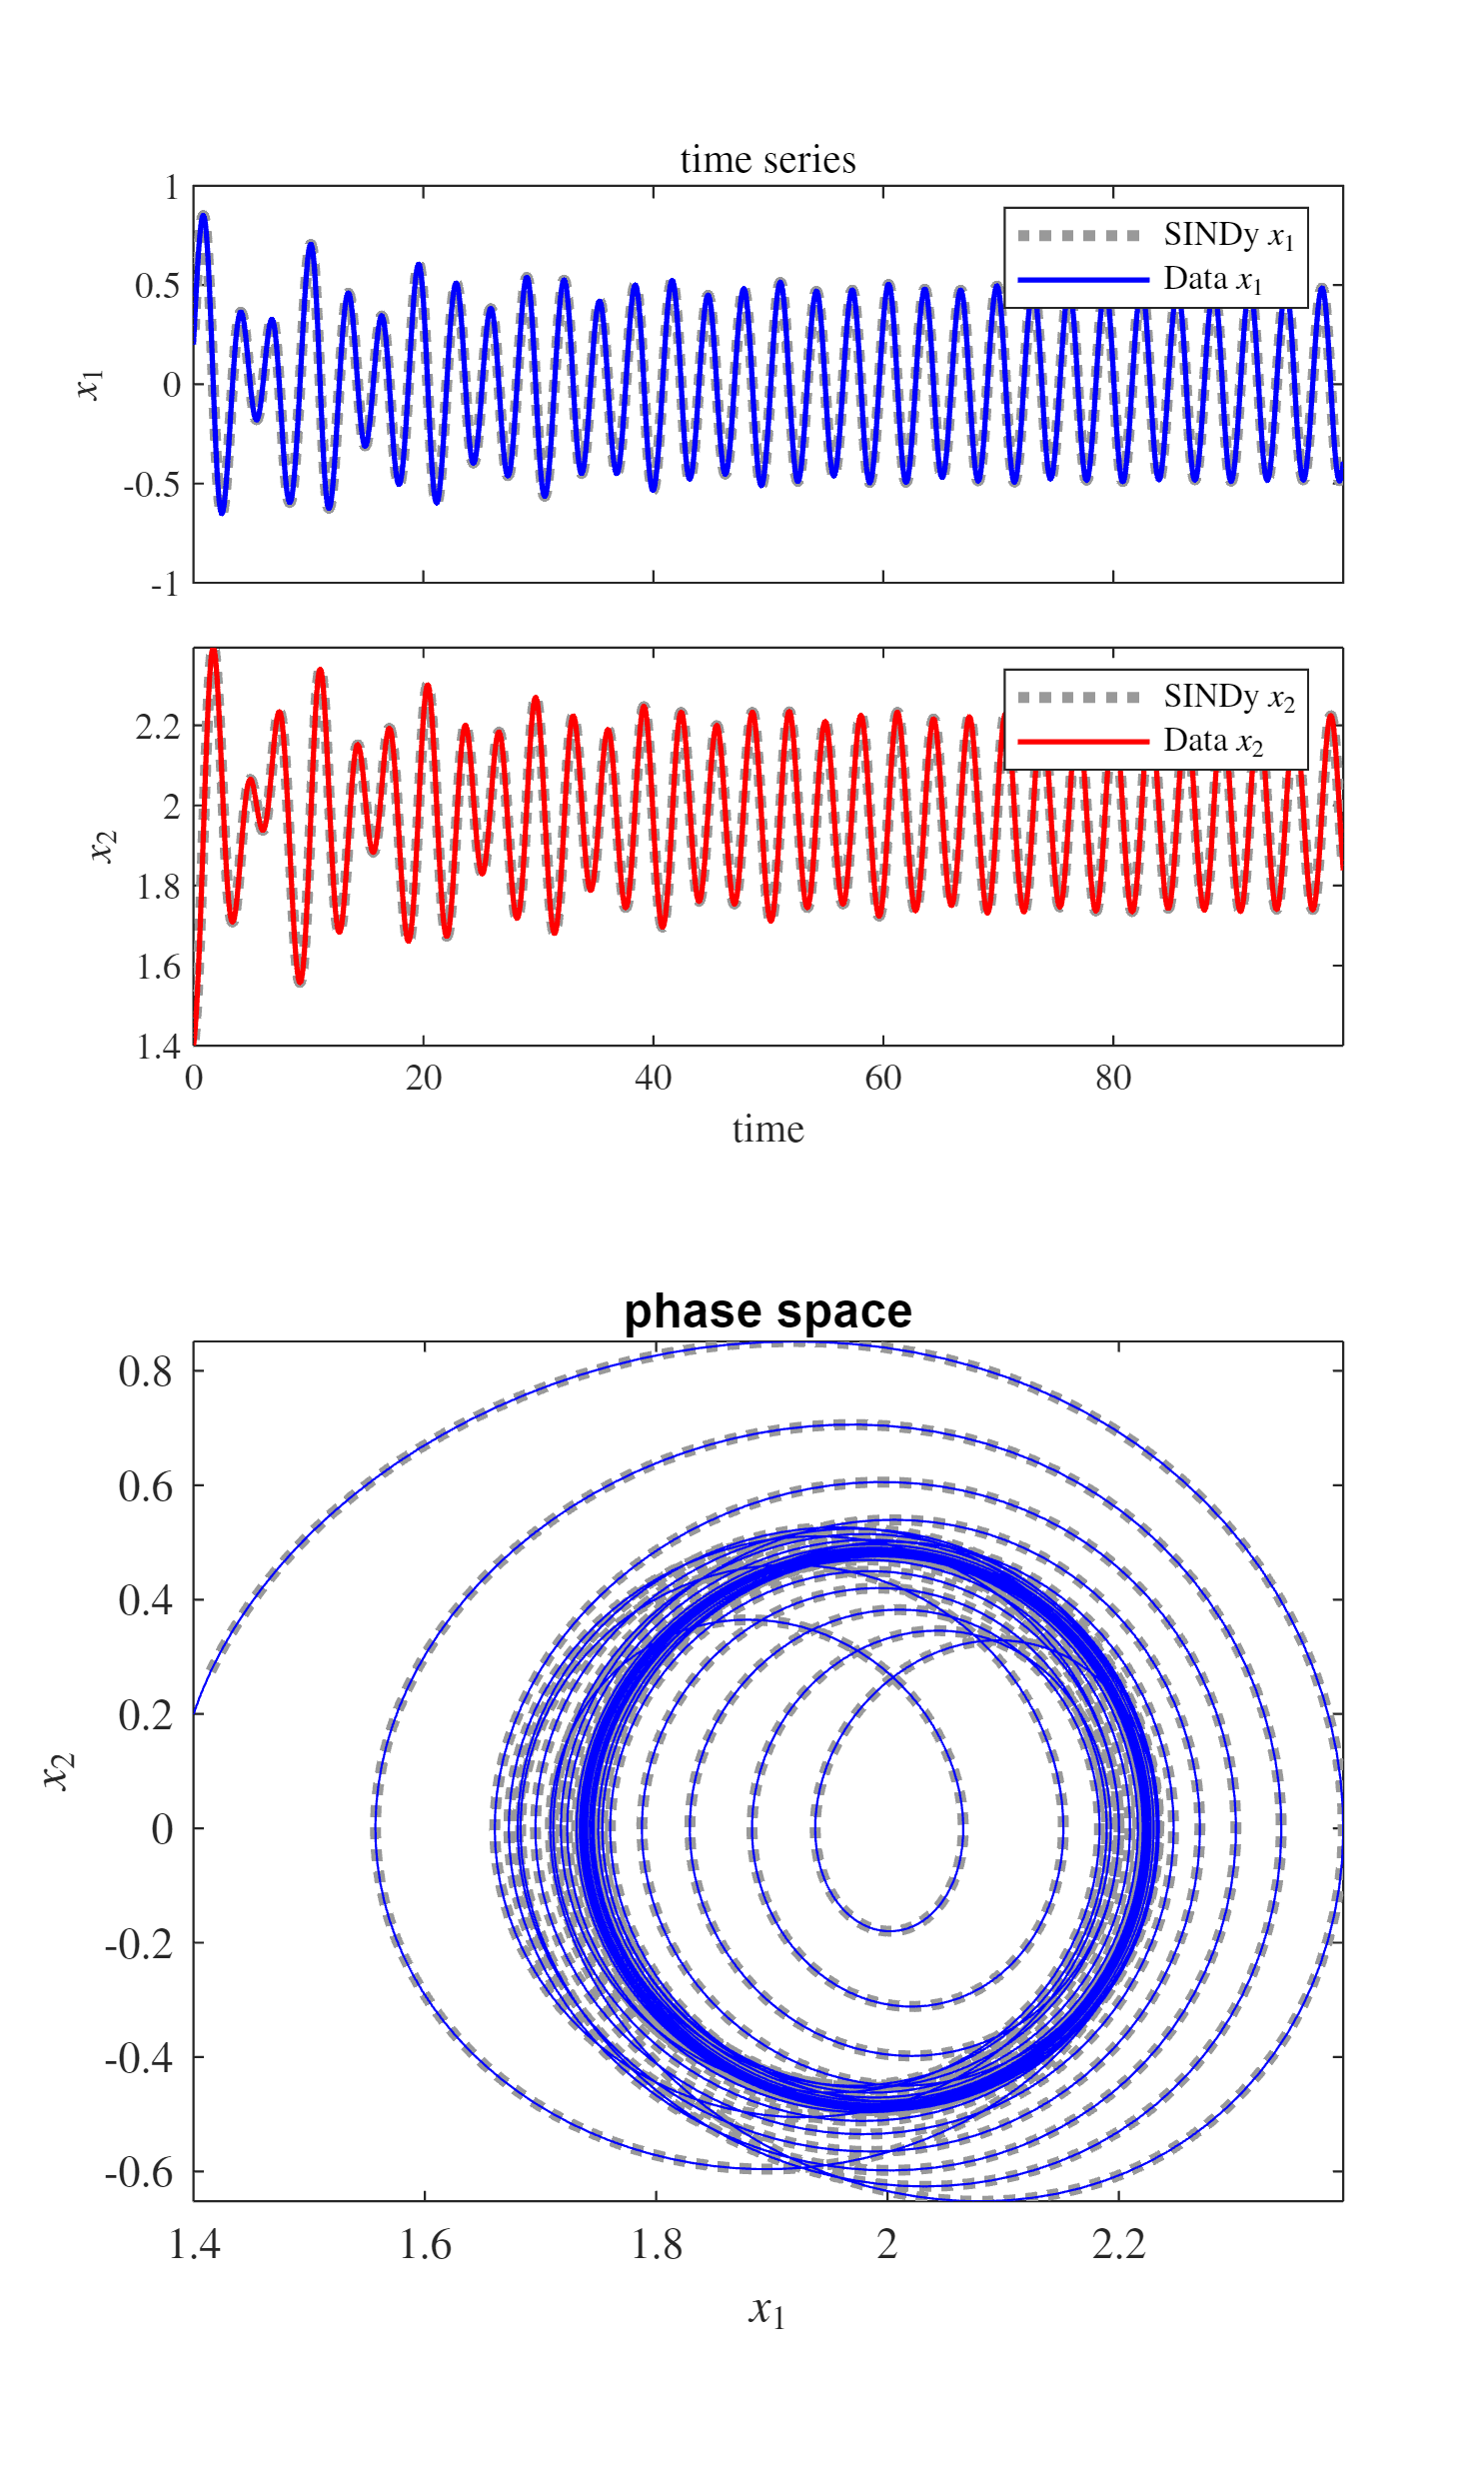

x0 = [0.2, 1.4]; % new initial condition
[t,x]=ode45(@(t,x) duffing(t,x,param),tspan,x0,options);

paramSINDy.Xi = Xi(:,1:2);
paramSINDy.polyorder = polyorder;
paramSINDy.paramDuffing = param;
[tSINDy,xSINDy]=ode45(@(t,x) SINDyODE_forced(t,x,paramSINDy),tspan,x0,options);

plotSINDy(t,x(:,1:2),tSINDy(3:end-2,:),xSINDy(3:end-2,:))